# MECH3465 | Coursework 2: Template

Replace the template title with your teams number!

## CW2: Coursework 2 - ** Robot Librarian!**

This coursework template is split into the 5 sections of the coursework.

**If you haven't read the brief then please download it from minerva**

You should explain your process during each stage, and each section of code you include should contain a short description of what you are doing and an overview of any MATLAB functions you have used and why.

### Add your own sub-headings to each main section!

This will keep things organised.

### Comment your code!

Before you say anything, I will admit my code has been quite poorly commented in some cases throughout the practicals, don't be like me, comment your code!

clear % Clear workspace variables 

## 0. Loading the Scenario

Download the URDF file from Minerva and save it somewhere, be aware that if you all work on the code together the file path may change depending on who's PC you are using and where they have saved the files!

You should change my default filepath, this will not work on your PC...

clear

Create a [`robotScenario`](docid:robotics_ref#mw_146ff228-e368-41e9-ac10-b70d38e44bd8) object.

scenario = robotScenario(UpdateRate=1,StopTime=10);

Create a [`rigidBodyTree`](docid:robotics_ref#bvan8uq-1) object of the custom CW2 URDF.

addpath("/Users/louieburns/Library/CloudStorage/OneDrive-UniversityofLeeds/Robotics Coursework/URDFs/Robot_URDF_V3/urdf")  % Louie Path folder
% addpath("C:\Users\dnehu\OneDrive - University of Leeds\Robotics Coursework\URDFs\Robot_URDF_V3\urdf")  % Dan path folder
savepath % Save filepath for next time

% Create a rigidBodyTree object of the Franka Emika Panda manipulator using loadrobot.
robotRBT = importrobot("Robot_URDF.urdf");
robotRBT.DataFormat = "row";  % or use "column" if you prefer

Create a `rigidBodyTree`-based [`robotPlatform`](docid:robotics_ref#mw_184989ef-41a5-4055-a8a4-5460899dbc3a) object using the manipulator model.

Robot = robotPlatform("Manipulator",scenario, ...
                      RigidBodyTree=robotRBT);

Create collision objects for all 6 books. - DO NOT EDIT BOOK POSITIONS IN THIS SECTION

book_1 = robotPlatform("Book_1",scenario,Collision="mesh", InitialBaseOrientation=[0.706923132	0.706925728	0.016057751	0.016057692], InitialBasePosition=[0.014018	-0.30839	0.10381]);
updateMesh(book_1,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0 0])

book_2 = robotPlatform("Book_2",scenario,Collision="mesh", InitialBaseOrientation=[0.706747289	0.706749885	0.022504157	0.022504074], InitialBasePosition=[-0.019668	0.30852	-0.032738]);
updateMesh(book_2,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0.682 0])
 
book_3 = robotPlatform("Book_3",scenario,Collision="mesh", InitialBaseOrientation=[0.40083391	0.400835382	-0.582522818	-0.582520678], InitialBasePosition=[0.28417	-0.10873	-0.082996]);
updateMesh(book_3,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 1 0])

book_4 = robotPlatform("Book_4",scenario,Collision="mesh", InitialBaseOrientation=[0.206562054	0.206562812	0.676264476	0.676261992], InitialBasePosition=[-0.16721	-0.24817	0.32703]);
updateMesh(book_4,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[0 1 0])

book_5 = robotPlatform("Book_5",scenario,Collision="mesh", InitialBaseOrientation=[0.636410903	0.636413241	0.308188293	0.308187161], InitialBasePosition=[-0.24541	0.19397	0.10258]);
updateMesh(book_5,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[0 1 1])

book_6 = robotPlatform("Book_6",scenario,Collision="mesh", InitialBaseOrientation=[0.276366618	0.276367633	0.650863095	0.650860704], InitialBasePosition=[-0.22945	-0.22148	0.10258]);
updateMesh(book_6,"Cuboid",Collision="mesh",Size=[0.025 0.1 0.07], Color=[1 0 1])


Visualize the scenario.

% hold off
% [ax,plotFrames] = show3D(scenario,Collisions="off");
% axis equal
% hold on
% view(79,36)
% light
% hold off

## 1. Forward Kinematics

### 1.1 Approach Overview

Write an overview of your approach to this main task here, and then continue to add comments to any code-sections you create to help explain the process.

Code comments, code-section text, figures, and presentation are all counted towards explanation marks.

### 1.2 Labelled Denavit-Hartenberg Frame Diagram

Download the CW2_Robot_Dimensions.PDF from Minerva and use it to solve the forward kinematics of the robot using the Denavit-Hartenberg assignment method. For more information look at back at the lecture on Forward Kinematics, it has a breakdown of the solutions.

Insert your nice diagram here.

### 1.3 Specify D-H Parameters and Produce a Table


$$\textrm{dhparams}=\left\lbrack A_{i\;} /a_{i\;} \;\;\;\;\;|\;\;\alpha_{i\;} \;\;\;\;\;\;|\;\;\;\;d_{i\;} \;\;\;\;|\;\;\;\;\theta {\;}_{i\;} \right\rbrack$$


dhparams = [ 0       pi/2    0.090   0;
             0.045   0       0       0;
             0.072   0       0       0;
             0.043   0       0       0 ];


## 2. Build Robot in MATLAB Robotics Toolbox

% We created our robot in solidworks and hence this was deleted

### Adding Robot Collisions 

showdetails(robotRBT)

--------------------
Robot: (6 bodies)

 Idx             Body Name      Joint Name      Joint Type             Parent Name(Idx)   Children Name(s)
 ---             ---------      ----------      ----------             ----------------   ----------------
   1                Link_1          Joint1        revolute                 Base_Link(0)   Link_2(2)  
   2                Link_2          Joint2        revolute                    Link_1(1)   Link_3(3)  
   3                Link_3          Joint3        revolute                    Link_2(2)   Link_4(4)  
   4                Link_4          Joint4        revolute                    Link_3(3)   End_Effector_1(5)  End_Effector_2(6)  
   5        End_Effector_1        Joint5_1       prismatic                    Link_4(4)   
   6        End_Effector_2        Joint5_2       prismatic                    Link_4(4)   
--------------------


home = homeConfiguration(robotRBT);

% ax = show(robotRBT, "Frames","off", "Collisions","off"); % Check robot loaded correctly

% Add collison to the end effector of your robot
addCollision(robotRBT.Bodies{end},"sphere",[0.005], trvec2tform([0,0,0])) % add new collision
addVisual(robotRBT.Bodies{end},"sphere",[0.005], trvec2tform([0,0,0]))

isColliding = checkCollision(robotRBT, homeConfiguration(robotRBT), IgnoreSelfCollision="on");

% Possibly useful functions: 
clearCollision(robotRBT.Bodies{1,4})

 **Reference: **For more shapes check out [checkCollision](https://uk.mathworks.com/help/robotics/ref/checkcollision.html#mw_4edbbc38-d51a-4356-94c6-68be8bb54566)

**NOTE: **If you choose to generate a URDF then you do not need to perform many of these steps.

## 3. Inverse Kinematics

Starting in the home configuration, solve for the arm reaching the point where the Book_1 frame lies.

### **Setup the Robot Trajectory Function**

function animateRobotTrajectory(scenario, Robot, q_start_deg, q_end_deg, numSteps)
    % animateRobotTrajectory Animates a robot moving from q_start to q_end.
    %
    %   animateRobotTrajectory(scenario, Robot, q_start_deg, q_end_deg, numSteps)
    %
    %   Inputs:
    %       scenario: The robotics scenario object.
    %       Robot: The robot object.
    %       q_start_deg: Start configuration in degrees (1x6 vector).
    %       q_end_deg: End configuration in degrees (1x6 vector).
    %       numSteps: Number of interpolation steps.

    % Convert degrees to radians
    q_start = deg2rad(q_start_deg);
    q_end = deg2rad(q_end_deg);

    % Time parameter from 0 to 1
    t = linspace(0, 1, numSteps);

    % Cosine-based scaling (ease-in/ease-out)
    s = 0.5 * (1 - cos(pi * t));  % smooth transition curve

    % Interpolate joint angles using s(t)
    q_traj = (1 - s') .* q_start + s' .* q_end;

    % Show scene once at the start
    hold off
    [ax, plotFrames] = show3D(scenario, Collisions="off");
    view(110, 20)
    axis equal
    light
    drawnow

    hold on

    % Store the current camera view to reuse
    [az, el] = view(ax);

    % Animate
    for k = 1:numSteps
        move(Robot, "joint", q_traj(k,:));     % Apply joint angles
        cla(ax);                               % Clear only axes content (not figure)
        show3D(scenario, Parent=ax, Collisions="off");  % Redraw into the same axes
        view(ax, az, el);                      % Restore camera view
        light
        drawnow
        pause(0.02);
    end
end

% Example usage:
% Assuming 'scenario' and 'Robot' are already defined:


**Robot Open Claw Function**

function q_after_grip = gripBook(Robot, scenario, ax, az, el, q_current)
    % Closes the robot's gripper fingers inward
    gripAngle = deg2rad(0.2);  % Adjust to your gripper range

    q_start = q_current;
    q_end = q_current;
    q_end(5) = gripAngle;     % Finger 1 inward
    q_end(6) = -gripAngle;    % Finger 2 inward

    % Animation steps
    numSteps = 20;
    t = linspace(0, 1, numSteps);
    s = 0.5 * (1 - cos(pi * t));
    q_traj = (1 - s') .* q_start + s' .* q_end;

    % Animate
    for k = 1:numSteps
        move(Robot, "joint", q_traj(k,:));
        cla(ax);
        show3D(scenario, Parent=ax, Collisions="off");
        view(110, 20)
        light
        drawnow
        pause(0.02);
    end

    q_after_grip = q_end;  % Return new joint configuration
end

% Copy this line to call this function
% q_gripped = gripBook(Robot, scenario, ax, az, el, q_traj(end,:));

**Robot Close Claw Function**

function q_after_release = releaseBook(Robot, scenario, ax, az, el, q_current)
    % Opens the robot's gripper fingers outward more than neutral
    releaseAngle = deg2rad(0.25);  % Outward flare angle — adjust as needed

    q_start = q_current;
    q_end = q_current;
    q_end(5) = -releaseAngle;   % Finger 1 outward
    q_end(6) = releaseAngle;    % Finger 2 outward

    % Animation steps
    numSteps = 20;
    t = linspace(0, 1, numSteps);
    s = 0.5 * (1 - cos(pi * t));
    q_traj = (1 - s') .* q_start + s' .* q_end;

    % Animate
    for k = 1:numSteps
        move(Robot, "joint", q_traj(k,:));
        cla(ax);
        show3D(scenario, Parent=ax, Collisions="off");
        view(110, 20)
        light
        drawnow
        pause(0.02);
    end

    q_after_release = q_end;
end

% Copy this line to call this function
% q_after_release = releaseBook(Robot, scenario, ax, az, el, q_gripped);

**Run the code for each of the positions**

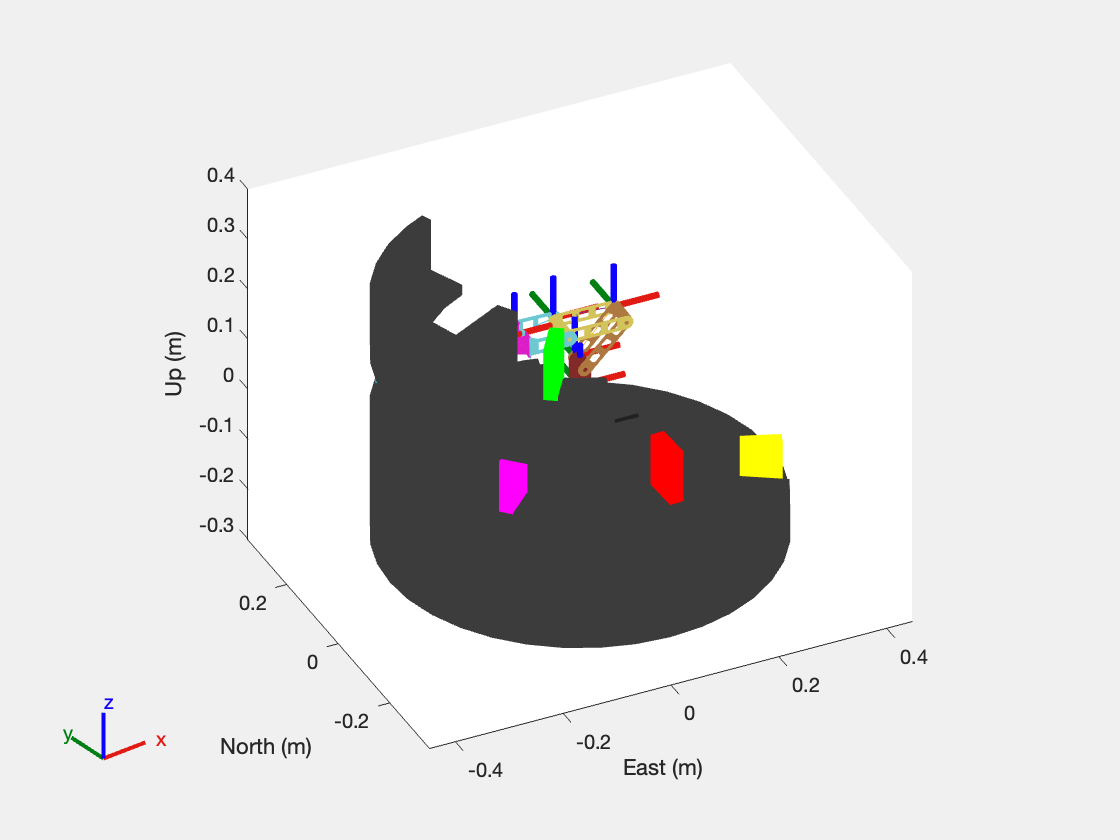

% Joint configurations matrix (degrees)
jointConfigsDeg = [
    0,     0,     0,     0,     0,     0;      % q_start_deg
    45,   -45,   -45,   -45,     0,     0;      % q_pos_1_open
    45,   -45,   -45,   -45,  0.5,  -0.5;      % q_pos_1_closed
    90,   -90,   -90,   -90,     0.5,     -0.5;      % q_pos_2_open
    90,   -90,   -90,   -90,  0,  0       % q_pos_2_closed
];

% Number of interpolation steps
numSteps = 40;

% Show initial scene and store view
[ax, plotFrames] = show3D(scenario, Collisions="off");
[az, el] = view(ax);

% Call the function for each trajectory
animateRobotTrajectory(scenario, Robot, jointConfigsDeg(1, :), jointConfigsDeg(2, :), numSteps);

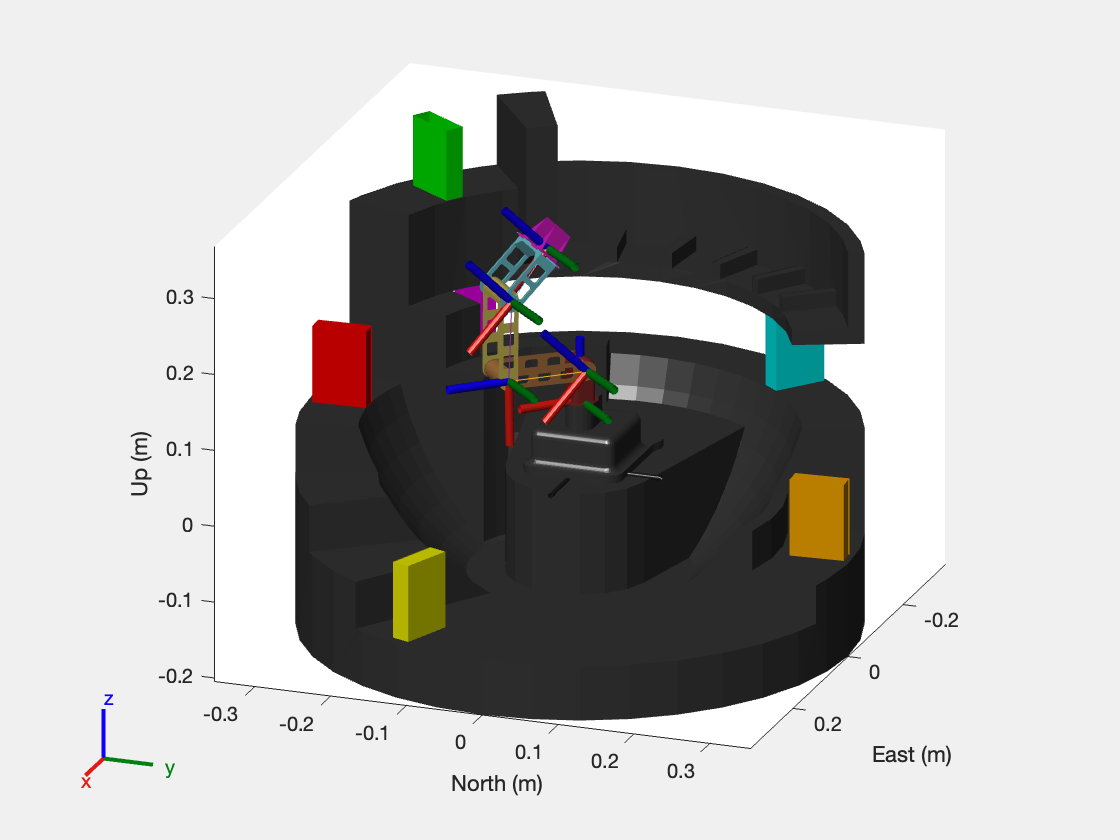

Error using cla (line 37)
Specify an axes object or array of axes objects.

Error in Movement_In_Template_V2>animateRobotTrajectory (line 97)
        cla(ax);                               % Clear only axes content (not figure)

animateRobotTrajectory(scenario, Robot, jointConfigsDeg(2, :), jointConfigsDeg(3, :), numSteps);

animateRobotTrajectory(scenario, Robot, jointConfigsDeg(3, :), jointConfigsDeg(4, :), numSteps);
animateRobotTrajectory(scenario, Robot, jointConfigsDeg(4, :), jointConfigsDeg(5, :), numSteps);



## 4. Trajectory Generation

Generate a trajectory for your End-Effector to follow such that the robots Tool Centre Point presses each of the books in the correct order. (20%)

###     4.1 Explain your approach 

Explain your approach to trajectory generation between each waypoint/via **(Max 200 words).**

###     4.2 Generate Theta Matrix

Matrix of theta values containing your robots joint angle data to be plotted in your animation.

## 5. Create your Animation/Video/Recording

You're on the home straight now!

It's time to prove your MATLAB plotting skills and generate the greatest gif you will ever create ...*within a MATLAB coding environment.*


% Remove the button from the rigidBodyTree once it has been pressed
% removeBody(Robot,"Link_B1") % Example code to remove button body


% % Gif stuff: Look up previous gif based practicals for guidance!
%     exportgraphics(gcf,'PleaseReviewTheModule.gif','Append',true);
%     w = warning('query','last');
%     id = w.identifier;
%     warning('off',id);

**NOTE: **I have not tested gif generation with this new scenario tool, we may need to use screen capture this year. Which will actaully speed matlab up, so that would be nice!

## Submission Instructions and Deadline

**Deadline: **Week 23 - Thursday @15:00 - 01/05/2025

**You will submit:**

- The complete code of your solution as a MATLAB Live Script, please also include outputs (e.g. do not clear the outputs after processing)

- Please, export your MATLAB Live Script as a PDF with the same file name. Only include outputs that are necessary to explain your process or those that show important milestones in the coursework (basically, please don't output everything making the document huge)

- Please refer to the hadnout for further instructions.

**MECH3465 CW2 2025 **| Written by ***George Jackson-Mills***

*Email: ****G.Jackson-Mills@Leeds.ac.uk***

Last edited: 18/03/2025